### Inizializzazione

fileName = 'dataset.xls';
dataTable = readtable(fileName, 'VariableNamingRule', 'preserve');
% categorie
category = dataTable.Category;
% valori numerici
X = dataTable{:, 2:end};
% nomi variabili
vlab = dataTable.Properties.VariableNames(2:end)';
vlab = deblank(vlab);

%PCA
npc = 2; % numero componenti principali
pret = 'as'; % preprocessing: 'as' (autoscaling) o 'mn' (mean centering)
if strcmpi(pret, 'mn')
    % calcola PCA con mean centering
    [loading, scores, eigenvalues, T2, varexpl] = pca(X, 'NumComponents', npc); 
    [residuals, ~] = pcares(X, npc);
    T2ok = mahal(scores, scores); % T2 corretto per il numero di PC scelte
elseif strcmpi(pret, 'as')
    % calcola PCA con autoscaling
    [loading, scores, eigenvalues, T2, varexpl] = pca(X, 'NumComponents', npc, 'VariableWeights', 'variance');
    [residuals, ~] = pcares(X, npc);
    loading = loading ./ std(X)'; % ricalcola i loadings per riflettere la scala originale
    T2ok = mahal(scores, scores); % T2 corretto per il numero di PC scelte
else
    error('Preprocessing non riconosciuto. Usa "mn" o "as".');
end
Q = sum(residuals.^2,2);
% qlim con box method 95% confidenza
m = mean(Q);
s = var(Q);
c = chi2inv(0.95, 2*m^2/s);
qlim_box = c*s/(2*m); 
% Limite T2 (limite di Hotelling) con 95% confidenza
nCampioni = size(T2,1);
T2limit = ((npc*(nCampioni^2-1))/(nCampioni*(nCampioni-npc)))*finv(0.95,npc,nCampioni-npc);

xa = 1; % PC1 sull'asse x
ya = 2; % PC2 sull'asse y

### Scores Plot

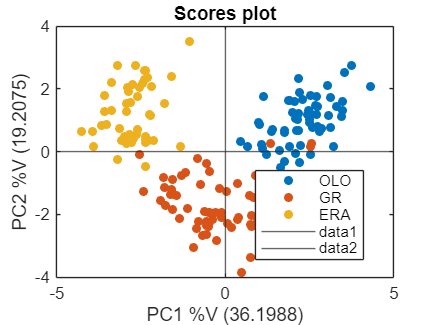

% grafico dei campioni nelle nuove coordinate PC
figure;
gscatter(scores(:,xa), scores(:, ya),category);
% griglia e assi
xline(0);
yline(0);
x_label=strcat('PC',int2str(xa),' %V (',num2str(varexpl(xa)),')');
xlabel(x_label)
y_label=strcat('PC',int2str(ya),' %V (',num2str(varexpl(ya)),')');
ylabel(y_label)
title('Scores plot')

### Loadings Plot

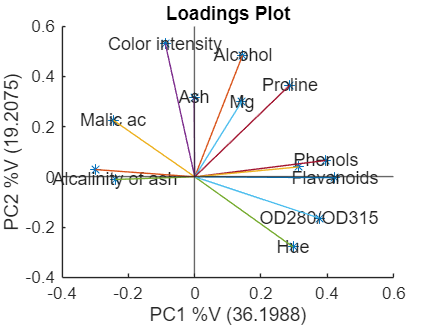

% grafico che mostra l'influenza delle variabili originali sulle PC
figure;
scatter(loading(:,xa), loading(:,ya),'*');
hold on;
textscatter(loading(:,xa),loading(:, ya),vlab) % aggiunta etichette
% frecce dall'origine ai loadings
for i = 1:size(X, 2)
    line([0, loading(i, xa)], [0, loading(i, ya)]);
end
% griglia e assi
xline(0);
yline(0);
x_label=strcat('PC',int2str(xa),' %V (',num2str(varexpl(xa)),')');
xlabel(x_label)
y_label=strcat('PC',int2str(ya),' %V (',num2str(varexpl(ya)),')');
ylabel(y_label)
title('Loadings Plot');

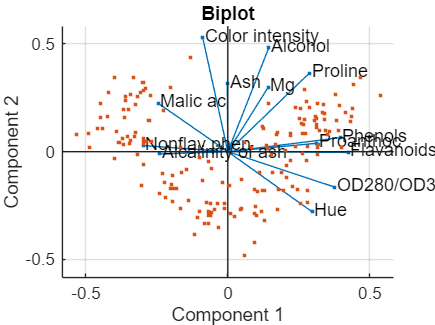

% biplot
figure
biplot(loading(:,[xa ya]),'Scores',scores(:,[xa ya]),'VarLabels',vlab);
title('Biplot');

### T2 vs Q (Grafico dei Residui)

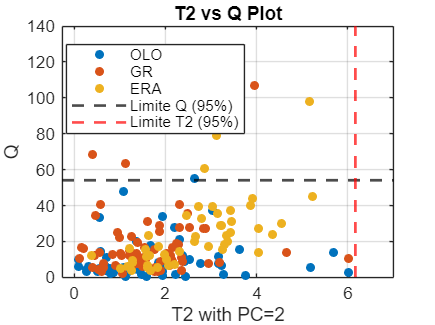

% Grafico per identificare campioni anomali
figure;
gscatter(T2ok,Q,category);
hold on;
grid on;
% griglia e assi
% limiti di confidenza
yline(qlim_box, '--k', 'LineWidth', 1.5, 'DisplayName', 'Limite Q (95%)'); 
xline(T2limit, '--r', 'LineWidth', 1.5, 'DisplayName', 'Limite T2 (95%)');
xlabel(strcat('T2 with PC= ', int2str(npc)))
ylabel('Q');
title('T2 vs Q Plot');